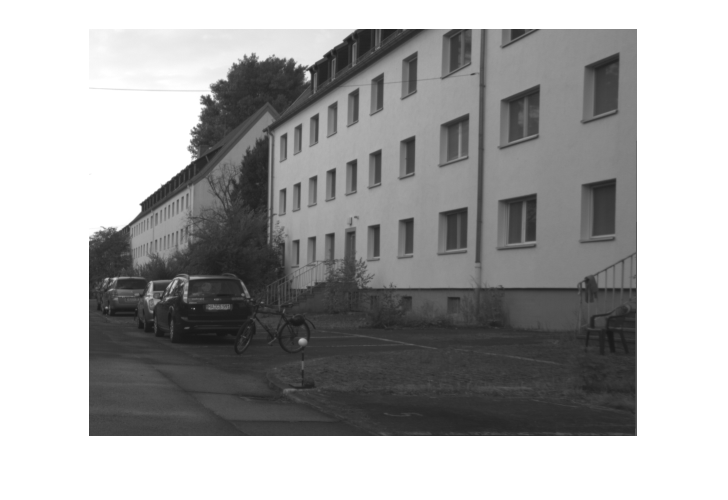

clear;

%Reading in and showing the image
original = im2double( imread( 'road', 'png' ) );
rgb_original = cat(3, original, original, original);
imshow( original )

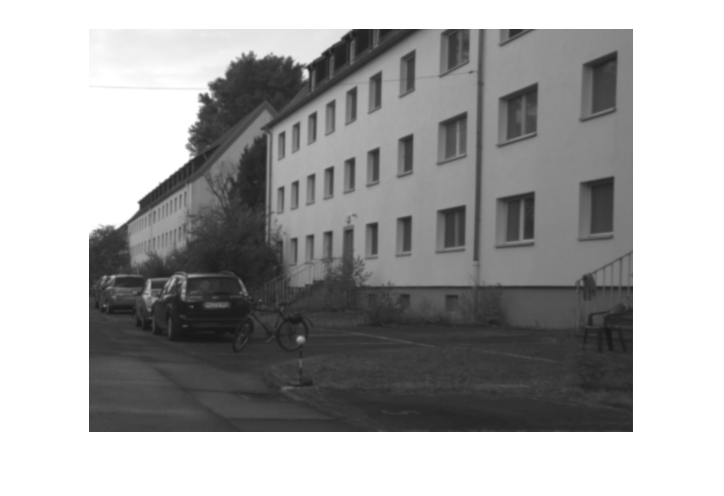


%Creating and using the Gaussian filter
sigma = 0.7;
dim = 2*ceil(2*sigma)+1;

gauss = fspecial('gaussian', dim, sigma);

smooth_image = my_filter( original, gauss );

imshow( smooth_image )

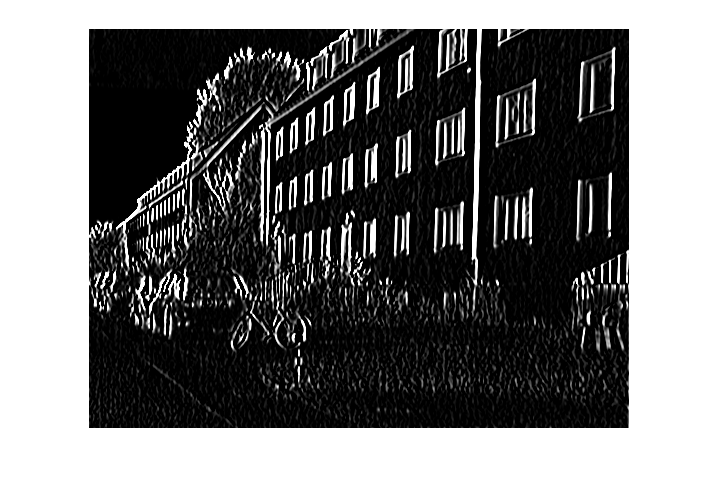


%Cleaning environment
clear gauss sigma dim

%Running the sobel derivation
sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_y = [1 2 1; 0 0 0; -1 -2 -1];

I_y = my_filter( smooth_image, sobel_y );
I_x = my_filter( smooth_image, sobel_x );

%Second-Order derivatives
I_yy = my_filter( I_y, sobel_y );
I_xx = my_filter( I_x, sobel_x );
I_xy = my_filter( I_x, sobel_y );
imshow( I_xx )

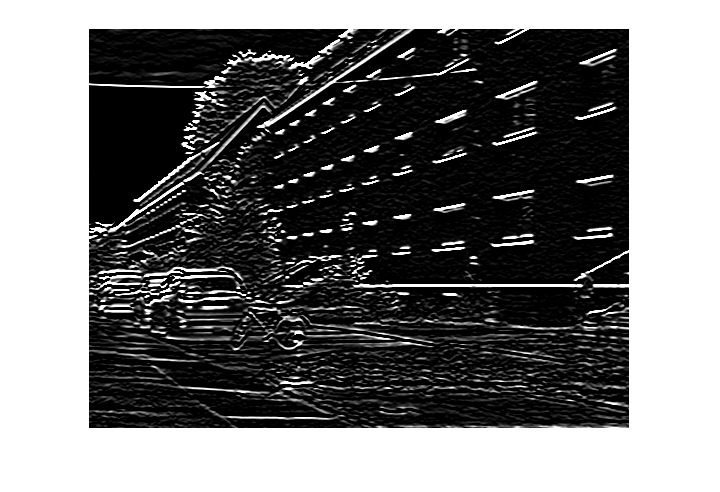

imshow( I_yy )

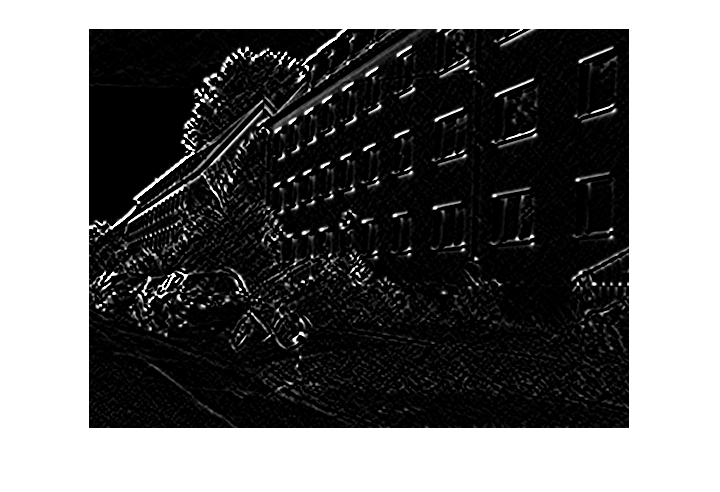

imshow( I_xy )

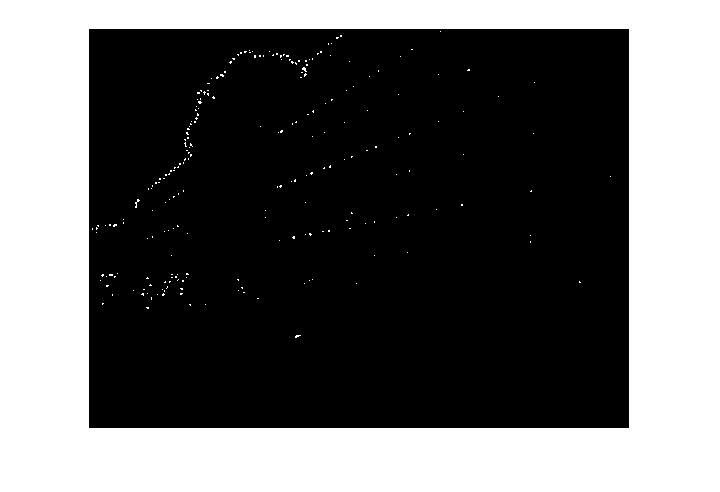


%Retrieving the Hessian
Hess = (I_yy .* I_xx) - (I_xy .^ 2);

%Thresholding the Hessian
thresh = 5;
Hess( Hess < thresh ) = 0;
imshow( Hess )

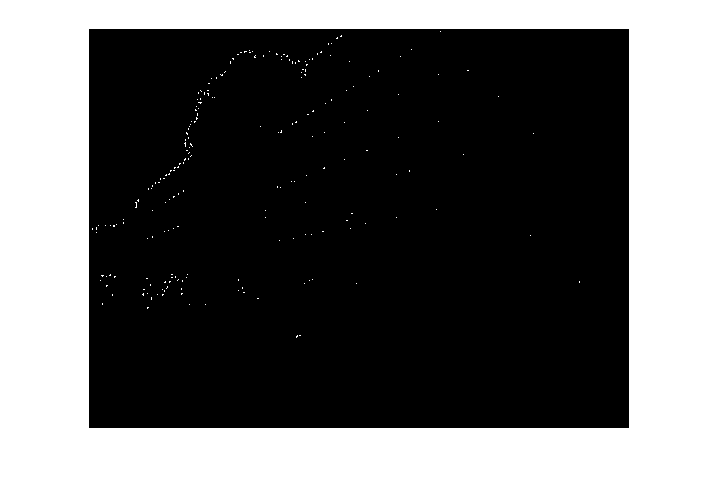


%Non-Maximum suppresion
determinant = atan( I_y ./ I_x );
determinant = determinant( 1:size(Hess, 1), 1:size(Hess, 2) );
Hessian_thresholded = non_max_suppression( Hess, determinant );
imshow( Hessian_thresholded )

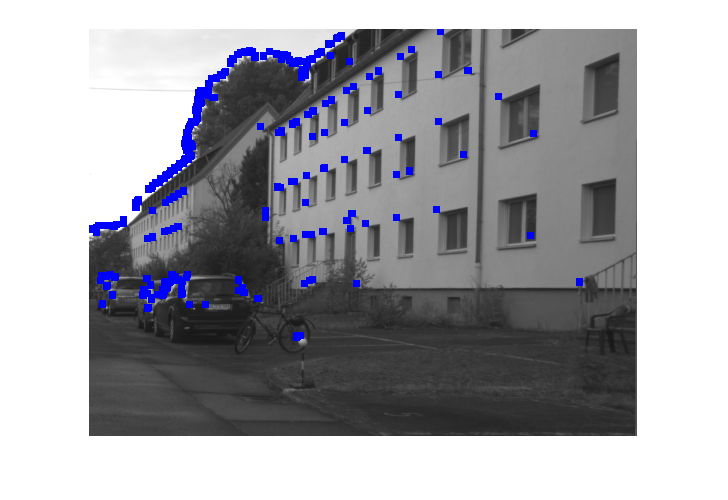


%Cleaning environment
clear I_x I_3y sobel_x sobel_y thresh

%Changing from an image object to a point-array
points = to_point_list( Hessian_thresholded );

%Superimpose the Hessian coords
Hessian_imposed = impose_circles( rgb_original, points );
imshow( Hessian_imposed )


%RANSAC the points
d = 5;
N = 200;
I = 20;
line1 = RANSAC( points, N, d, I);
new_points = remove_inliers( line1, points, d);
line2 = RANSAC( new_points, N, d, I );
new_points = remove_inliers( line2, new_points, d);
line3 = RANSAC( new_points, N, d, I );
new_points = remove_inliers( line3, new_points, d);
line4 = RANSAC( new_points, N, d, I );
RANSAC_lines = cat(1, line1, line2, line3, line4 )

RANSAC_lines =     17   197   252     8
    59   250   113    63
   210    32     0     0
   219    86    60   279


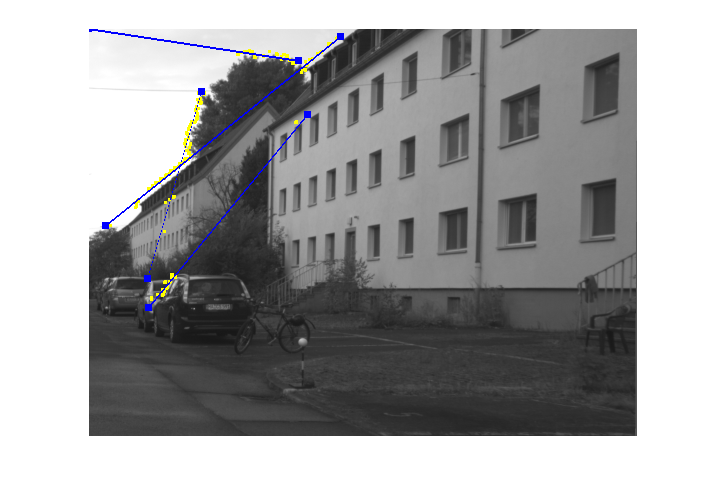

with_inliers = print_inliers( rgb_original, RANSAC_lines, points, d );
with_lines = draw_line_segment( with_inliers, RANSAC_lines );
imshow( with_lines )

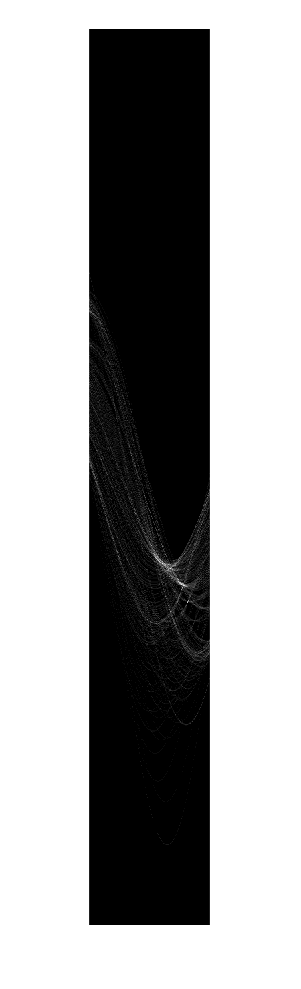


clear new_points line1 line2 line3 line4 N I with_inliers

%HOUGH transform
hough = my_hough( points, size(Hessian_thresholded, 1), size(Hessian_thresholded, 2), 1 );
imshow( hough );

hough_lines = get_lines( hough )

hough_lines =    -0.8098  257.4205
   -0.7536  270.8473
   -0.9004  240.6107
   -1.0000  224.8600


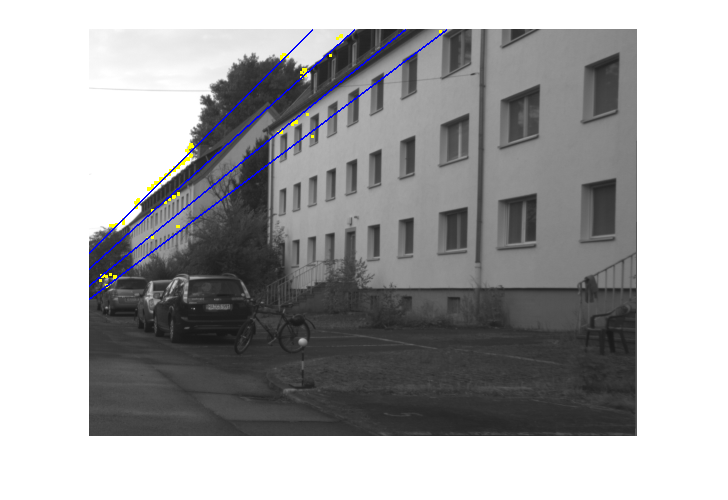

with_inliers = plot_hough_inliners( rgb_original, hough_lines, points, d );
with_hough_lines = draw_line( with_inliers, hough_lines);
imshow( with_hough_lines )